A0 = readmatrix("C:\Users\mgorbun\Documents\MATLAB\kemia-FTIR\Si-membrane\bare03.02.13.16.f.dat");
A1 = readmatrix("C:\Users\mgorbun\Documents\MATLAB\kemia-FTIR\Si-membrane\bareFaceToAp03.02.14.19.f.dat");
% A2 = readmatrix("C:\Users\mgorbun\Documents\MATLAB\kemia-FTIR\Si-membrane\mmFaceToAp03.02.13.54.f.dat");
% A3 = readmatrix("C:\Users\mgorbun\Documents\MATLAB\kemia-FTIR\Si-membrane\mmFaceToAp03.02.14.06.f.dat");
% A4 = readmatrix("C:\Users\mgorbun\Documents\MATLAB\kemia-FTIR\Si-membrane\wavenumber.dat");
% A5 = readmatrix("C:\Users\mgorbun\Documents\MATLAB\kemia-FTIR\Si-membrane\");
disp(1)

     1



% A0 = movmean(A0, 30);
% A1 = movmean(A1, 30);
A2 = movmean(A2, 100);
% A3 = movmean(A3, 10);
% A4 = movmean(A4, 10);

A0(:,2) = A1(:,2) ./ A3(:,2);

y = A0(:,2);
idx = find(diff(sign(diff(y))) < 0) + 1;   % кандидаты максимумов
thr = 0.8*max(y);                          
idx = idx(y(idx) > thr);  

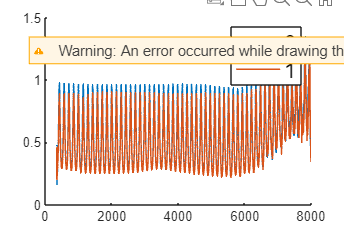

lw = 1;
figure
hold on
plot(A4, A0(:,1), "LineWidth", lw, "DisplayName", "0")
plot(A4, A1(:,1), "LineWidth", lw, "DisplayName", "1")
% plot(A4, A2(:,1), "LineWidth", lw, "DisplayName", "2")
% plot(A4, A3(:,1), "LineWidth", lw, "DisplayName", "3")
% plot(A4(:,1), A4(:,2), 'r-', "LineWidth", lw, "DisplayName", "4")
% plot(A5(:,1), A5(:,2), 'b-', "LineWidth", lw, "DisplayName", "5")
% scatter(A0(idx,1), A0(idx,2))
legend("FontSize", 15)

fid = fopen('C:\Users\mgorbun\Documents\MATLAB\kemia-FTIR\Si-membrane\bare03.02.13.16.f.dat');
C = textscan(fid,'%s',1,'HeaderLines',2);
fclose(fid);
